dog = imread("C:\Users\97254\Desktop\Guy\Scripts\playground\dog.jpg");
dog = flip(dog,2);
init_height = size(dog,1) ; init_width = size(dog,2);
min_size = min(init_height,init_width);
dog = dog((1+floor(init_height/2)-floor(min_size/2)):(floor(init_height/2)+floor(min_size/2)),(1+floor(init_width/2)-floor(min_size/2)):(floor(init_width/2)+floor(min_size/2)),:);
% dog = dog(1:2:end,1:2:end,:);

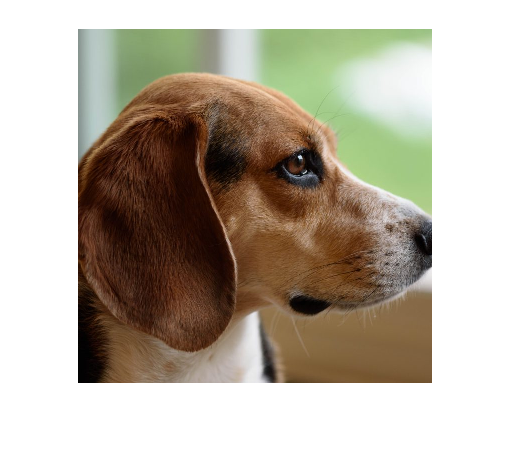

imshow(dog(1:2:end,1:2:end,:))

% n = 100;
% logical_row = logical(repmat([ones(1,floor(size(dog,2)/n/2)) zeros(1,floor(size(dog,2)/n/2))],1,n));
% logical_col = logical(repmat([ones(floor(size(dog,1)/n/2),1) zeros(floor(size(dog,1)/n/2),1)],1,n));
% 
% tiledlayout(1,3)
% nexttile
% imshow(dog(:,logical_row,:))
% nexttile
% imshow(dog(:,~logical_row,:))
% nexttile
% imshowpair(dog(:,logical_row,:),dog(:,~logical_row,:))